# Add paths

clearvars
close all
addpath(fullfile('.','SINDy'));
addpath(fullfile('.','Learn++NSE'));
addpath(fullfile('.','ConceptDriftData'));
addpath(genpath(fullfile('.','advlearn')));

## Generate data or load data??

%T = 200;  % number of time stamps
%N = 100;  % number of data points at each time
%[data_train, labels_train,data_test,labels_test] = ConceptDriftData('sea', T, N);
dataset = "X2CDT";
x = load("Synthetic Datasets\" + dataset + ".mat");
data_train = x.(dataset).dataTrain;
data_test = x.(dataset).dataTest;
labels_test = x.(dataset).labelsTest;
labels_train = x.(dataset).labelsTrain;
T = length(data_train);
for t = 1:T
  data_train{t} = data_train{t};
  labels_train{t} = labels_train{t};
  data_test{t} = data_test{t};
  labels_test{t} = labels_test{t};
end

## These cell arrays are structured as {class}{1,timeStep}

numTimeSteps = length(data_train);
[numObs, numDims] = size(data_train{1});
numClasses = numel(unique(labels_train{1}));
classLabelsIdxs = cell(numTimeSteps,numClasses);
classData = cell(numTimeSteps,numClasses);
classMeans = cell(numTimeSteps,numClasses);
classVariances = cell(numTimeSteps,numClasses);
numObsPerClass = cell(numTimeSteps,numClasses);
for iClass = 1:numClasses
	[classLabelsIdxs(:,iClass)] = cellfun(@(x) eq(x,iClass),labels_train',...
                              'UniformOutput',false); % Get indexes for data points of classNumber at each time step
	[classData(:,iClass)] = cellfun(@(a,b) a(b,:),data_train',classLabelsIdxs(:,iClass),...
                        'UniformOutput',false); % Now extract the class data using logical indexing at each time step 
	[classMeans(:,iClass)] = cellfun(@(x) mean(x),classData(:,iClass),...
                           'UniformOutput',false); % Calculate the means at every time step
	[classVariances(:,iClass)] = cellfun(@(x) cov(x),classData(:,iClass),...
                               'UniformOutput',false); % Calculate the covariance at every time step
    [numObsPerClass(:,iClass)] = cellfun(@(x) size(x,1), classData(:,iClass),...
                               'UniformOutput',false);
end

## structure array of variables and stuff, each row is a time step

nseData = repmat(struct("dataTrain",zeros(numObs,numDims),...
                        "dataTest",zeros(numObs,numDims),...
                        "labelsTrain",zeros(numObs,1),...
                        "labelsTest",zeros(numObs,1)),1,numTimeSteps);
[nseData.dataTrain] = data_train{:};
[nseData.dataTest] = data_test{:};
[nseData.labelsTrain] = labels_train{:};
[nseData.labelsTest] = labels_test{:};
classInfo = repmat(struct("mu",zeros(1,numDims),...
                               "sigma",zeros(numDims,numDims),...
                               "data",zeros(numObs,numDims),...
                               "numObs",0,...
                               "idx",false(numObs,1)),numTimeSteps,numClasses);
[classInfo(:,:).mu] = classMeans{:,:};
[classInfo(:,:).sigma] = classVariances{:,:};
[classInfo(:,:).data] = classData{:,:};
[classInfo(:,:).numObs] = numObsPerClass{:,:};
[classInfo(:,:).idx] = classLabelsIdxs{:,:};

## Prepare data for SINDy

SINDyData = repmat(struct("mu",0,"sigma",0),numTimeSteps,numClasses);
for iClass = 1:numClasses
    for iTStep = 2:numTimeSteps
        SINDyData(iTStep,iClass).mu = vertcat(classInfo(1:iTStep,iClass).mu);
        SINDyData(iTStep,iClass).sigma = classInfo(iTStep-1,iClass).sigma;
    end
end
clearvars -except numTimeSteps numObs numDims nseData numClasses dataset classInfo SINDyData

## Classifier parameters

model.type = 'SVM';          % base classifier
net.a = .5;                   % slope parameter to a sigmoid
net.b = 10;                   % cutoff parameter to a sigmoid
net.threshold = 0.01;         % how small is too small for error
net.mclass = 2;               % number of classes in the prediciton problem
net.base_classifier = model;  % set the base classifier in the net struct
net.initialized = true;
net.classifiers = {};   % classifiers
net.w = [];             % weights 
net.initialized = false;% set to false
net.t = 1;              % track the time of learning
net.classifierweigths = {};               % array of classifier weights
net.type = 'learn++.nse';

## Create a SINDy model for means, 1 Obj that will be continuously updated.

for iTStep = numTimeSteps:-1:1
    for iClass = numClasses:-1:1
        SINDyArray(numTimeSteps,numClasses) = SINDy(); % SINDy Object ... type help SINDy for list of what each parameter does
    end
end
[SINDyArray.lambda] = deal(8e-3);
[SINDyArray.polyOrder] = deal(1);
[SINDyArray.useSine] = deal(0);
[SINDyArray.sineMultiplier] = deal(10);
[SINDyArray.useExp] = deal(0);
[SINDyArray.expMultiplier] = deal(10);
[SINDyArray.useCustomPoolData] = deal(1);
[SINDyArray.nonDynamical] = deal(0);
% TVRegDiff parameters for SINDy 
[SINDyArray.useTVRegDiff] = deal(0);
[SINDyArray.iter] = deal(10); 
[SINDyArray.alph] = deal(0.00002);
[SINDyArray.ep] = deal(1e12);
[SINDyArray.scale] = deal("small");
[SINDyArray.plotflag] = deal(0);
[SINDyArray.diagflag] = deal(0);

## paths needed for utilizing chris's library, add the paths for your system and restart matlab if matlab cant find them

p = py.sys.path;
insert(p,int32(0), pwd + "\advlearn\")
insert(p,int32(0), pwd + "\advlearn\advlearn\attacks\poison\")
insert(p,int32(0), pwd + "\advlearn\advlearn\attacks\")
% insert(p,int32(0),'C:\Users\Delengowski-Mobile\Documents\Gits\AttackingLearnPP.NSE\advlearn\')
% insert(p,int32(0),'C:\Users\Delengowski-Mobile\Documents\Gits\AttackingLearnPP.NSE\advlearn\advlearn\attacks\poison\')
% insert(p,int32(0),'C:\Users\Delengowski-Mobile\Documents\Gits\AttackingLearnPP.NSE\advlearn\advlearn\attacks\')

## SVMAttack Parameters

Setup Boundary Regions need to set this up for any dataset

atkSet.step_size = 0.5;
atkSet.timeToAttack = 3;
atkSet.max_steps = 100;
atkSet.c = 1;
atkSet.kernel = 'linear';
atkSet.degree = 3;
atkSet.coef0 = 1;
atkSet.gamma = 1;
atkSet.numAtkPts = 49;
% Mesh and step is for creating boundary of attack
atkSet.mesh = 10.5;
atkSet.step = 0.25;
% variables to hold attack points and generated data sets
genDistr = repmat(struct("data",zeros(numObs,numDims),"labels",zeros(numObs,1)),1,numTimeSteps);
atkData = repmat(struct("points",zeros(atkSet.numAtkPts,numDims),...
                           "labels",zeros(atkSet.numAtkPts,1)),1,numTimeSteps);
[genDistr(1:atkSet.timeToAttack-1).data] = deal(0);
[genDistr(1:atkSet.timeToAttack-1).labels] = deal(0);
[atkData(1:atkSet.timeToAttack-1).points] = deal(0);
[atkData(1:atkSet.timeToAttack-1).labels] = deal(0);
%np = py.importlib.import_module('numpy');

## run learn++.nse, and attack

nseResults = repmat(struct("net",net,...
                              "f_measure",zeros(1,net.mclass),...
                              "g_mean",0,...
                              "recall",zeros(1,net.mclass),...
                              "precision",zeros(1,net.mclass),...
                              "errs_nse",0,...
                              "latestClassifier",0),1,numTimeSteps);
for iTStep = 1:numTimeSteps
    if iTStep >= atkSet.timeToAttack-1 % dont start attacking until timestep before time to attack
        for iClass = 1:numClasses
            SINDyArray(iTStep,iClass).buildModel(SINDyData(iTStep,iClass).mu,1,1,iTStep,1);
            % Generate distribution for next time step
            % last row of SINDy.model is the predicted time step
            genDistr(iTStep+1).data(classInfo(iTStep,iClass).idx,:) = ...
                               mvnrnd(SINDyArray(iTStep,iClass).model(end,:),...
                                      SINDyData(iTStep,iClass).sigma,...
                                      classInfo(iTStep,iClass).numObs);
            genDistr(iTStep+1).labels(classInfo(iTStep,iClass).idx,:) = ...
                          repmat(iClass,classInfo(iTStep,iClass).numObs,1);
        end
    end
    if iTStep < atkSet.timeToAttack % perform Learn++.NSE 
        if iTStep == 1
            [nseResults(iTStep).net,...
            nseResults(iTStep).f_measure,...
            nseResults(iTStep).g_mean,...
            nseResults(iTStep).precision,...
            nseResults(iTStep).recall,...
            nseResults(iTStep).errs_nse,...
            nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep).net,...
                                                nseData(iTStep).dataTrain,...
                                                nseData(iTStep).labelsTrain,...
                                                nseData(iTStep).dataTest,...
                                                nseData(iTStep).labelsTest);
        else
            [nseResults(iTStep).net,...
            nseResults(iTStep).f_measure,...
            nseResults(iTStep).g_mean,...
            nseResults(iTStep).precision,...
            nseResults(iTStep).recall,...
            nseResults(iTStep).errs_nse,...
            nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep-1).net,...
                                                nseData(iTStep).dataTrain,...
                                                nseData(iTStep).labelsTrain,...
                                                nseData(iTStep).dataTest,...
                                                nseData(iTStep).labelsTest);
        end
    elseif iTStep >= atkSet.timeToAttack % perform Learn++.NSE with attack points added
        maxBounds = max(genDistr(iTStep).data);
        minBounds = min(genDistr(iTStep).data);
        % need to construct boundary for n dimensional dataset
        for iDim = 1:numDims
           atkSet.boundary(iDim,1) = minBounds(iDim);
           atkSet.boundary(iDim,2) = maxBounds(iDim);
        end
        [atkData(iTStep).points,atkData(iTStep).labels] = ...
                                    chrisAttacks(genDistr(iTStep).data,...
                                                 genDistr(iTStep).labels,...
                                                 atkSet);
		[nseResults(iTStep).net,...
		nseResults(iTStep).f_measure,...
		nseResults(iTStep).g_mean,...
		nseResults(iTStep).precision,...
		nseResults(iTStep).recall,...
		nseResults(iTStep).errs_nse,...
        nseResults(iTStep).latestClassifier] = ...
        learn_nse_for_attacking(nseResults(iTStep-1).net,...
                                [nseData(iTStep).dataTrain;atkData(iTStep).points],...
                                [nseData(iTStep).labelsTrain;atkData(iTStep).labels'],...
                                nseData(iTStep).dataTest,...
                                nseData(iTStep).labelsTest);

    end
end

## Plotting Of Just data, attack points, and generated data

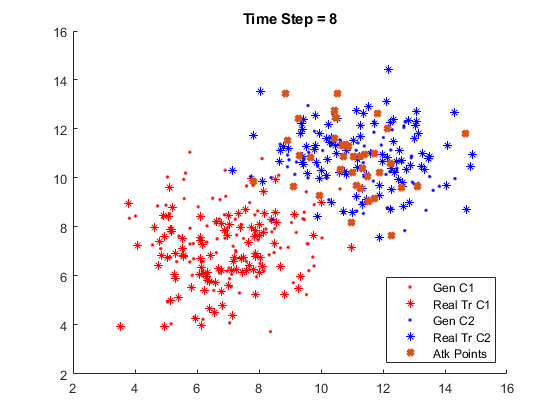

timeStep = 8;
plotSVMData = false;
plotResults(classInfo,genDistr,atkData,nseResults,timeStep,plotSVMData)

## SINDy Learned Functions

timeStep = 3;

#### Class 1

SINDyArray(timeStep,1).learnedFunctions

ans = 3×2 table
                       d1dot      d2dot 
                     _________    ______

    1                  0.91457    1.0996
    d1^(0)*d2^(1)    -0.065209         0
    d1^(1)*d2^(0)            0         0


#### Class 2

SINDyArray(timeStep,2).learnedFunctions

ans = 3×2 table
                      d1dot        d2dot  
                     ________    _________

    1                 0.49171         1.39
    d1^(0)*d2^(1)    0.059752    -0.043303
    d1^(1)*d2^(0)    0.043303    -0.031381


function [] = plotResults(classInfo,genDistr,atkData,nseResults,timeStep,plotSVMData)
    classColors = ["r" "b"];
    figure
    hold on
    for iClass = 1:size(classInfo,2)
    plot(genDistr(timeStep).data(genDistr(timeStep).labels == iClass,1),...
         genDistr(timeStep).data(genDistr(timeStep).labels == iClass,2),...
         classColors(iClass)+".")
     plot(classInfo(timeStep,iClass).data(:,1),classInfo(timeStep,iClass).data(:,2),...
          classColors(iClass)+"*")
    end
    plot(atkData(timeStep).points(:,1),atkData(timeStep).points(:,2),...
        'x','Color',[0.8500 0.3250 0.0980],'LineWidth',3)
    if plotSVMData == true
        maxBounds = max(genDistr(timeStep).data);
        minBounds = min(genDistr(timeStep).data);
            % need to construct boundary for n dimensional dataset
        mdl = nseResults(timeStep).net.classifiers{1, end}.classifier;
        f = @(x) -(x*mdl.Beta(1) + mdl.Bias)/mdl.Beta(2);
        x = linspace(minBounds(1),maxBounds(1));
        plot(x,f(x),'g--','LineWidth',2)
        plot(mdl.SupportVectors(:,1),mdl.SupportVectors(:,2),'kO','MarkerSize',3)
    end
    hold off
    title("Time Step = " + timeStep)
    legend('Gen C1','Real Tr C1','Gen C2','Real Tr C2','Atk Points','Boundary','Support Vectors','Location','SouthEast')
end